clc
clear all
close all

## Parameters

Kernel = 'polynomial';
KernelScale = 1.3;
Direction = 'backward';

% 40 settimane - 86.8%
% Kernel = 'polynomial';
% KernelScale = 1.3;
% Direction = 'backward';

% 3 mesi - 82.5%
% Kernel = 'polynomial';
% KernelScale = 1;
% Direction = 'forward';

## LOAD DATA

[Dataset] = load_dataset(0); %1 if you want to detect outliers
%writetable(Dataset,'Dataset.csv');

## FEATURE SELECTION

Data = Dataset{:,1:end-1};
%Data(5,:) = [];
Labels = [zeros(19,1) ; ones(19,1)]; %MODIFICARE IN BASE AL DATASET

Sequential


%c = cvpartition(Labels,'Holdout',0.3); 
% %partiziono dataset 0,3 e' il 30% del dataset come il testset
c = cvpartition(Labels,'LeaveOut');
opts = statset('display','iter');

classf = @(train_data,train_labels,test_data,test_labels) ...
        sum(predict(fitcsvm(train_data,train_labels,'KernelFunction', Kernel, ...
        'PolynomialOrder', [], ...
        'KernelScale', KernelScale, ... 
        'BoxConstraint', 1, ...
        'Standardize', true), test_data) ~= test_labels); 
[fs,history] = sequentialfs(classf,Data,Labels,'cv',c,'options',opts,'direction',Direction);

Start backward sequential feature selection:
Initial columns included:  all
Columns that must be included:  none
Step 1, used initial columns, criterion value 0.368421
Step 2, removed column 15, criterion value 0.315789
Step 3, removed column 12, criterion value 0.289474
Step 4, removed column 1, criterion value 0.289474
Step 5, removed column 6, criterion value 0.263158
Step 6, removed column 5, criterion value 0.236842
Step 7, removed column 11, criterion value 0.236842
Step 8, removed column 8, criterion value 0.236842
Step 9, removed column 9, criterion value 0.184211
Step 10, removed column 18, criterion value 0.157895
Step 11, removed column 14, criterion value 0.131579
Final columns included:  2 3 4 7 10 13 16 17 



%}

Fscnca

% mdl = fscnca(Dataset{:,1:end-1},Dataset{:,end});
% figure(1)
% plot(mdl.FeatureWeights,'ro')
% grid on
% xlabel('Feature index')
% ylabel('Feature weight')

Relieff

% [ranks,weights] = relieff(Dataset{:,1:end-1},Dataset{:,end},10);
% 
% %Create a bar plot of predictor importance weights.
% bar(weights(ranks))
% xlabel('Predictor rank')
% ylabel('Predictor importance weight')

Dimensionality reduction

fprintf('Sono state selezionate le features:');

Sono state selezionate le features:

Dataset(1,fs)

Dataset.Properties.VariableNames

ans = 1×19 cell array
    {'VelHandsCorrelation'}    {'AccHandsCorrelation'}    {'JerkHandsCorrelation'}    {'VelFeetCorrelation'}    {'AccFeetCorrelation'}    {'JerkFeetCorrelation'}    {'skew1'}    {'skew_hands'}    {'skew_feet'}    {'Area_Nose'}    {'Area_Hands'}    {'Area_Feet'}    {'Area0_Nose'}    {'Area0_Hands'}    {'Area0_Feet'}    {'Periodicity_Nose'}    {'Periodicity_Hands'}    {'Periodicity_Feet'}    {'Labels'}


Dataset =  [ Dataset(:,fs) Dataset(:,end)]; 

## TRAINING

trainedClassifier = struct with fields:
    RequiredVariables: {38×1 cell}


Failed prediction of ITEM number 13
Failed prediction of ITEM number 20
Failed prediction of ITEM number 25
Failed prediction of ITEM number 26
Failed prediction of ITEM number 36


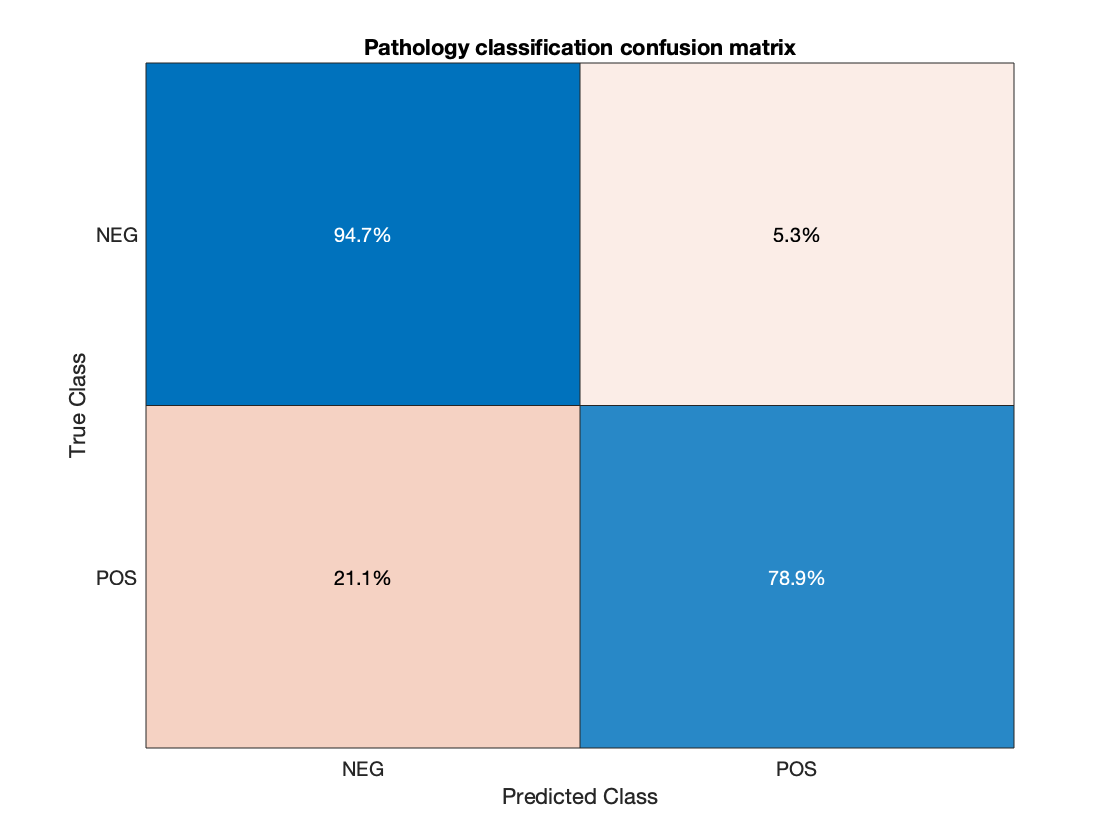

AUC = 0.8310

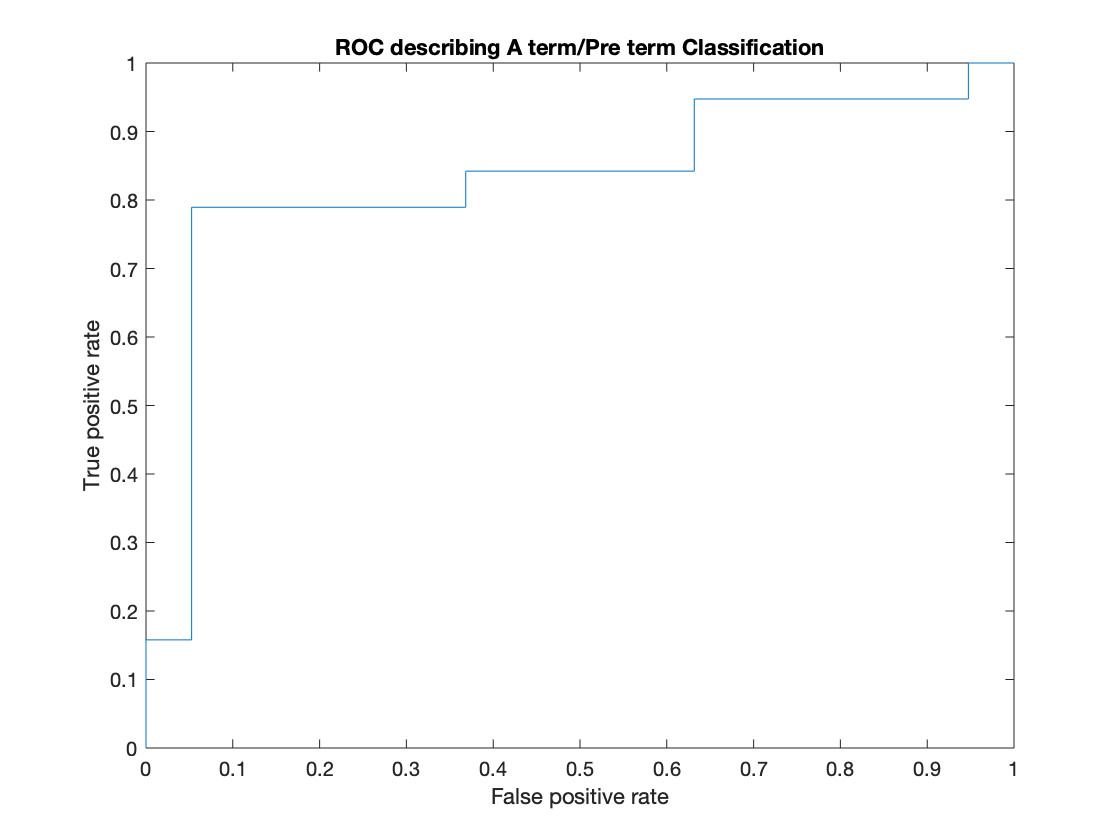

[trainedClassifier, validationAccuracy] = trainClassifier(Dataset,Kernel,KernelScale);


fprintf('The Trainig accuracy is %.1f%% \n',validationAccuracy*100);

The Trainig accuracy is 86.8% 
